# Object detection and pose estimation for cuboid objects

### Overview

The perception process involves two main steps,

- Training and validation: This process involves training the RGB-based object detection network (YOLO v4) and its validation against the test dataset.

- Online object detection process: This process involves the pose estimation using real-time raw RGBD data using a pre-trained YOLO v4 network and Principle Component Analysis (PCA).

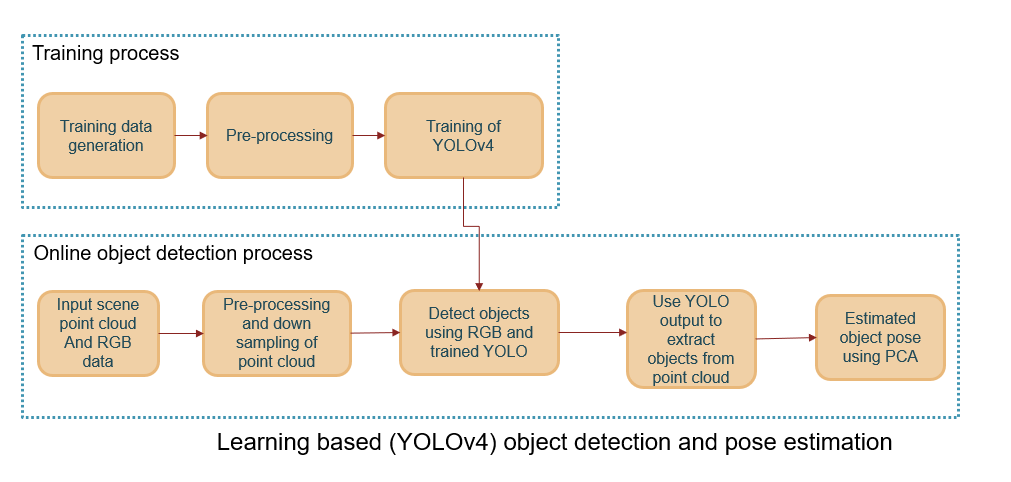

This script explains the steps involved in the pose estimation of cuboid objects. The script will be using the sample image and point cloud data available with this project.

#### Download the pre-trained YOLO v4 network and dataset

You need to download the dataset and pre-trained network from [this](https://ssd.mathworks.com/supportfiles/UniversalRobots/IntelligentBinPickingDataSet/Cuboidal_Object_Dataset_Real.zip) link. We have used pre-trained network in this script for showing the perception pipeline.

**Note: Downloading the content from this link is necessary to run this example as it includes the pre-tranined network and training dataset.**

#### Read sample point cloud and sample RGB data  

rgbImage = imread("sample_rgbImage.png");
ptCloud = pcread("sample_ptCloud.ply");

#### Detect objects using trained YOLO v4 network

The YOLO v4 detector trained to detect cuboid objects is available as 'trainedYOLOv4Detector_cuboid' along with this example

Set this flag to true if you want to see the outputs

showPartialOutputs = true;

Load pre-trained network

pretrained = load('trainedYOLOv4Detector_cuboid.mat');
trainedYoloNet = pretrained.detector; %YOLO v4 network

Compute the bounding box using the loaded detector

[bboxes,scores,labels] = detectObjectsYoloNet(trainedYoloNet,rgbImage);

Visualize the computed bounding box with the raw RGB input data

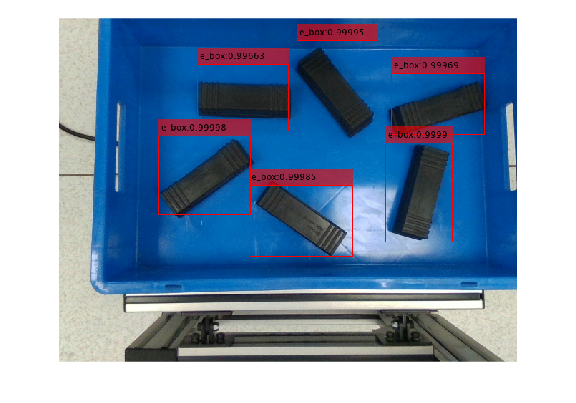

if(showPartialOutputs)
    % visualize the detected object bounding box
    annotatedImage = insertObjectAnnotation(im2uint8(rgbImage), 'Rectangle',...
        bboxes, string(labels)+":"+string(scores),'Color','r');
    figure, imshow(annotatedImage);
end

choose objects which have a detection confidence score higher than `yoyloScoreTh` for further processing

valid_idx = scores > yoyloScoreTh;
bboxes = bboxes(valid_idx, :);
scores = scores(valid_idx);
labels = labels(valid_idx);
numObjects = size(bboxes,1);

#### Detect the plane and remove the plane from the point cloud

In this section, we remove the plane from the raw point cloud data for the further computation.

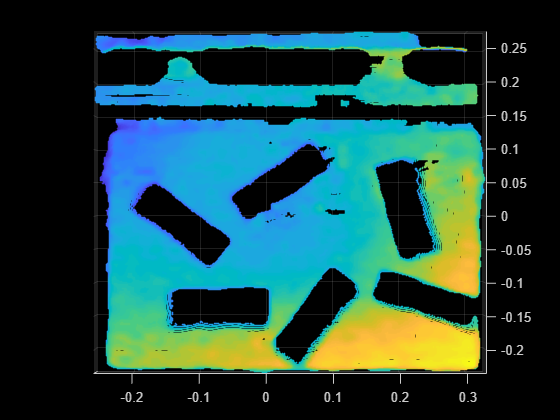

[param, planeIdx, nonPlaneIdx] = pcfitplane(ptCloud, PlanrThickness, normalvector, maxPlaneTilt);

plane = select(ptCloud, planeIdx);
nonPlane = select(ptCloud, nonPlaneIdx);
if(showPartialOutputs)
    figure,pcshow(plane,'ViewPlane','XY');axis on;
end


% non-plane mask
[m,n,~] = size(rgbImage);
nonPlaneMask = zeros(m,n);
nonPlaneMask =nonPlaneMask(:);
nonPlaneMask(nonPlaneIdx)= 1;

## Estimate object poses

This section estimates the object poses using the bounding box and pre-processed point cloud data.

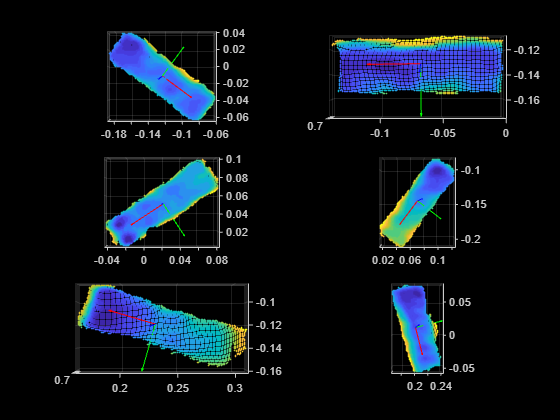

[xyz,theta,ptCloud_vec,scene_pca_vec] = findObjectPoses(ptCloud,rgbImage, bboxes, gridDownsample, nonPlaneMask);

if(showPartialOutputs)
    figure;
    for idx = 1: numObjects
        U = scene_pca_vec{idx}.UVW(:,1);
        V = scene_pca_vec{idx}.UVW(:,2);
        W = scene_pca_vec{idx}.UVW(:,3);
        center = scene_pca_vec{idx}.centroid;
        nexttile;
        pcshow(ptCloud_vec{idx},'ViewPlane','XY');
        hold on;
        quiver3(center(1), center(2), center(3), U(1), V(1), W(1), 'r');
        quiver3(center(1), center(2), center(3), U(2), V(2), W(2), 'g');
        quiver3(center(1), center(2), center(3), U(3), V(3), W(3), 'b');
        hold off;
    end
end